clear; clc; close all;
addpath('src');
addpath('src\EM');
addpath('src\GC');

lambda1 = 0.9;
lambda2 = 0.9;
reso = 1;     % image resolution

## preprocessing

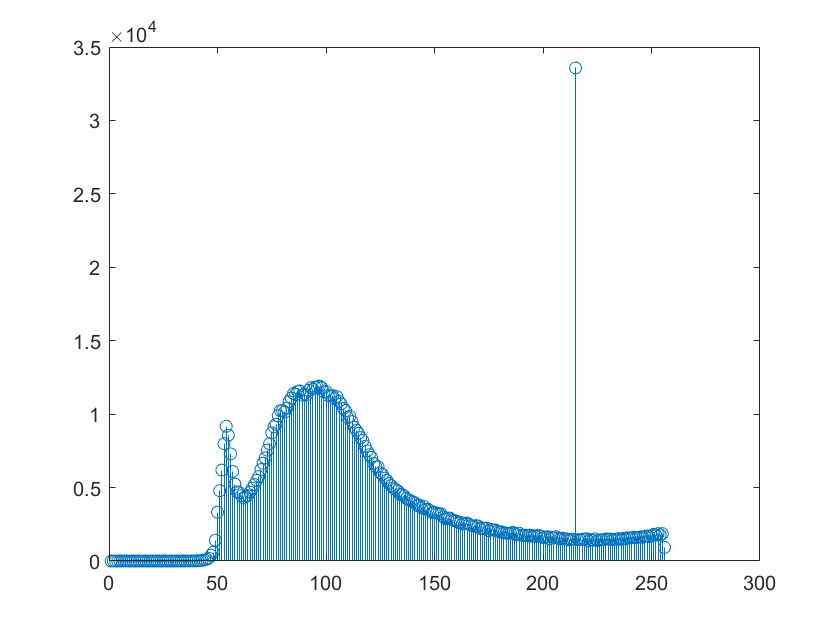

[img1,map1] = imread('D:\data\GAMMA_fil\fil2.bmp','bmp');
[img2,map2] = imread('D:\data\GAMMA_fil\fil6.bmp','bmp');
img1 = double(round(img1));
img2 = double(round(img2));

[M,N,H] = size(img1);

im1_hist = imhist16(img1);
figure;
stem(im1_hist)

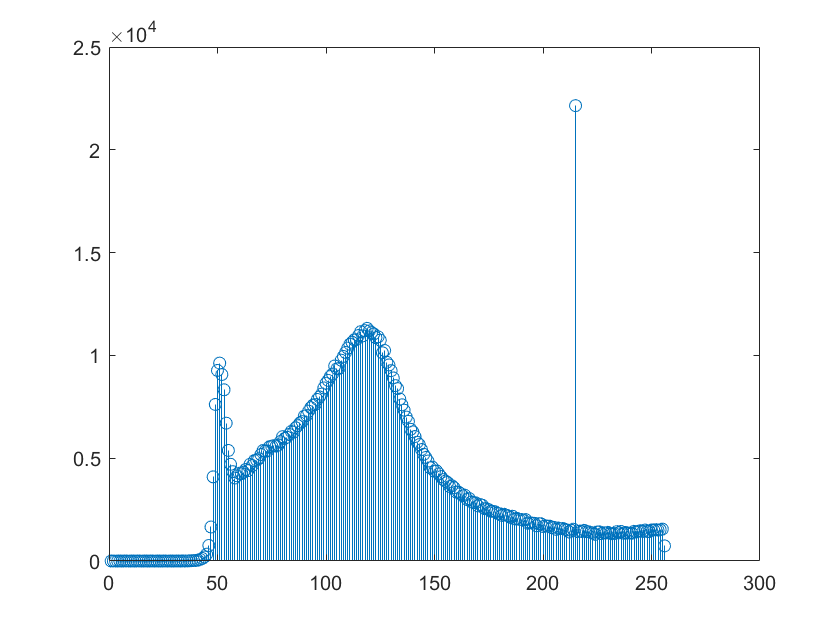


im2_hist = imhist16(img2);
figure;
stem(im2_hist)

## radiation correction

% t_min = 0; t_max = 1;
% img1 = rad_corr(img1,t_min,t_max);
% img2 = rad_corr(img2,t_min,t_max);
% 
% im1_hist = imhist16(uint8(img1) + 1);
% figure;
% 
% stem(im1_hist)
% 
% im2_hist = imhist16(uint8(img2) + 1);
% figure;
% stem(im1_hist)

## add MBI and calculate difference image

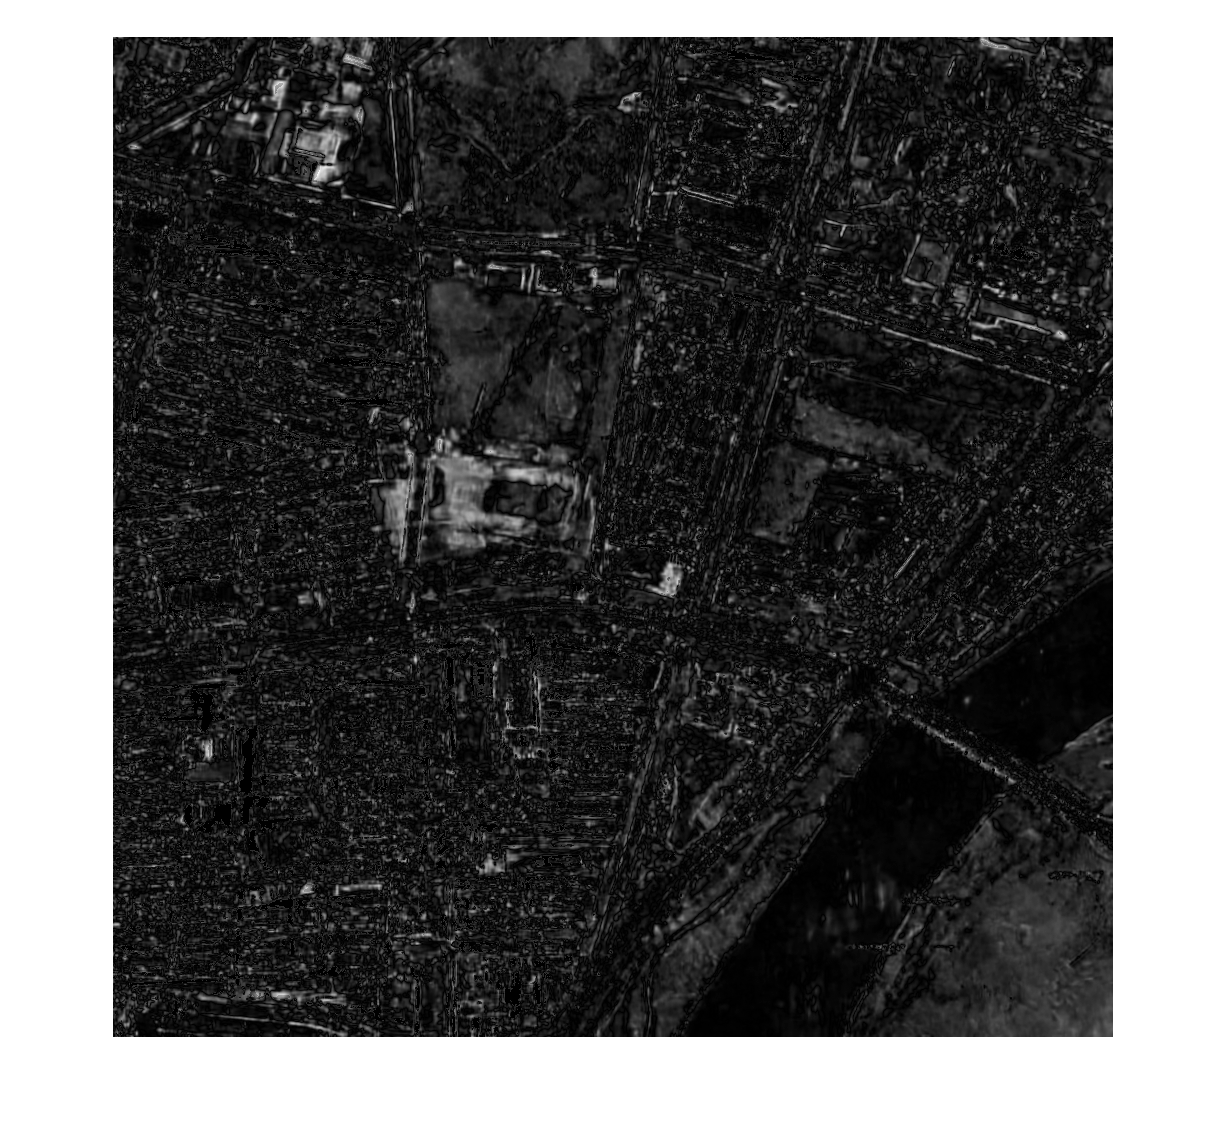

% load ..\cosegmentation_data\MBI;
% MBI1 = cal_MBI(img1);
% MBI2 = cal_MBI(img2);
% img1 = cat(3,img1,MBI1);
% img2 = cat(3,img2,MBI2);
Ic = img_diff(img1,img2);
figure;
imshow(Ic,[]);

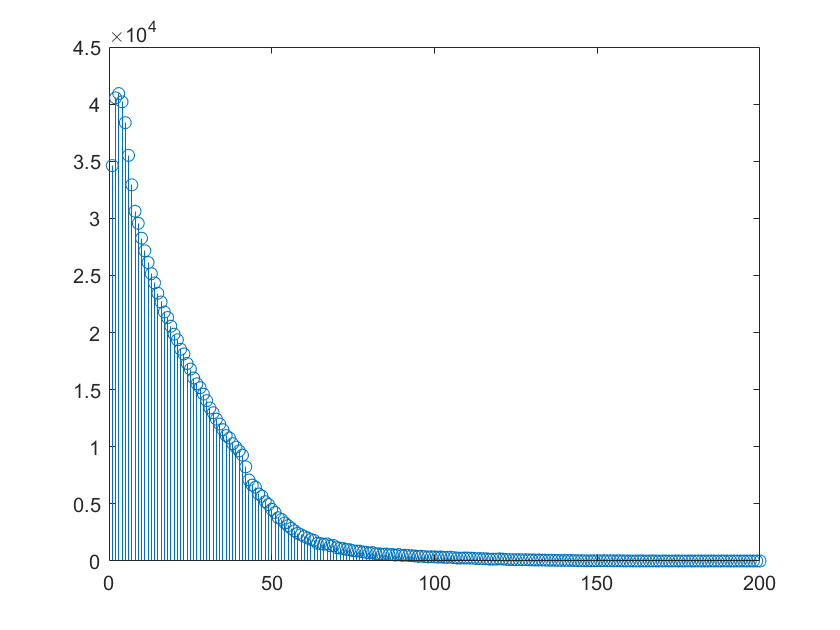

Ic_hist = imhist16(Ic);
figure;
stem(Ic_hist)

## calulate threshold using Bayes theory

[T_theory,T_experiment,gamma] = cal_threshold(Ic);
T = 44;


T2=graythresh(Ic);
% %% build graph and calculate edge weights
% [termWeights_1, edgeWeights_1] = cal_weight(img1,Ic,lambda1,T);
% [termWeights_2, edgeWeights_2] = cal_weight(img2,Ic,lambda2,T);
% 

## graph-cut algorithm for cosegmentation

% [cut_1, labels_1] = graphCutMex(termWeights_1, edgeWeights_1);
% [cut_2, labels_2] = graphCutMex(termWeights_2, edgeWeights_2);
% 

## fragmentation Removal

% seg1 = reshape(labels_1, [M,N]);
% seg2 = reshape(labels_2, [M,N]);
% 
% figure;
% imshow(seg1);
% title('seg1 before frag_remove')
% figure;
% imshow(seg2);
% title('seg2 before frag_remove')
% 
% seg1 = frag_remove(seg1,reso);
% seg2 = frag_remove(seg2,reso);
% 
% figure;
% imshow(seg1);
% title('seg1 after frag remove')
% figure;
% imshow(seg2);
% title('seg2 after frag remove')
% 

## Correspondence Establishment

% [seg1_oa,seg2_oa] = overlay_analysis(seg1,seg2);
% [seg1_show,seg2_show] = assign_label(seg1_oa,seg2_oa);
% 
% 
% 
% 
% 